clc;
clearvars;
load('IdentStat.mat')
u = DataStatW(:,1);
N = length(u)

N = 2501

yw = DataStatW(:,2);
yc = DataStatC(:,2);

# parameter identification

phi = [ones(N,1) 1./u 1./u.^2 1./u.^3]; %capital phi
Pw = (phi'*phi)\phi'*yw % with white noise

Pw =    10.1381
    0.9104
   -0.1804
    0.0987


Pc = (phi'*phi)\phi'*yc % with color noise

Pc =    10.6697
    0.5716
   -0.1068
    0.0937


## estimated values and errors generated

yhatw = phi*Pw;
yhatc = phi*Pc;
erw = yw - yhatw;
erc = yc - yhatc;

## plot results for white noise

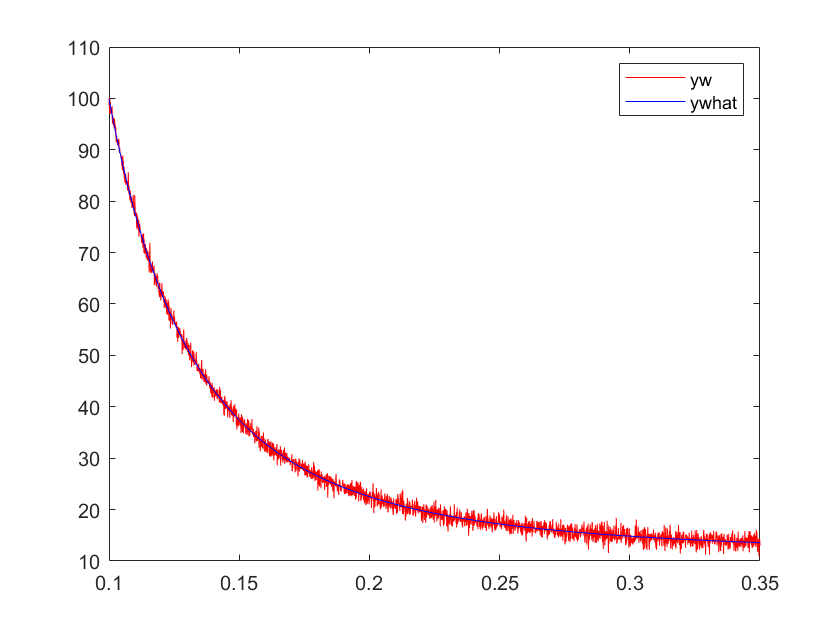

plot(u, yw, 'r-')
hold on
plot(u, yhatw, 'b-')
hold off

legend('yw', 'ywhat')

## plot results for color noise

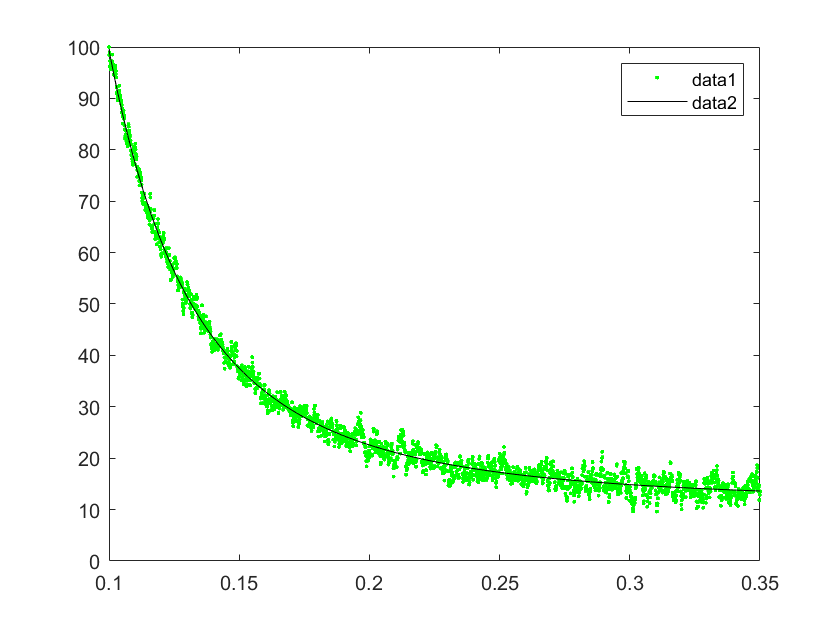

plot(u, yc, 'g.')
hold on
plot(u, yhatc, 'k-')
hold off

legend('show')

## covariance and confidence level

% covariance 
d = length(Pw)

d = 4

sigma2w = (1/(N-d))*sum(erw.^2)

sigma2w = 1.0522

sigma2c = (1/(N-d))*sum(erc.^2)

sigma2c = 2.6695

covpw1 = sigma2w*inv(phi'*phi) % using #inv function

covpw1 =     0.3716   -0.2071    0.0355   -0.0019
   -0.2071    0.1170   -0.0203    0.0011
    0.0355   -0.0203    0.0036   -0.0002
   -0.0019    0.0011   -0.0002    0.0000


covpw2 = sigma2w./(phi'*phi) % using forward slash as #inv

covpw2 = 	1.0e+-3 *

    0.4207    0.0839    0.0147    0.0023
    0.0839    0.0147    0.0023    0.0003
    0.0147    0.0023    0.0003    0.0000
    0.0023    0.0003    0.0000    0.0000


covpc1 = sigma2c./(phi'*phi)

covpc1 =     0.0011    0.0002    0.0000    0.0000
    0.0002    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000


covpc2 = sigma2c*inv(phi'*phi)

covpc2 =     0.9427   -0.5255    0.0901   -0.0048
   -0.5255    0.2968   -0.0515    0.0028
    0.0901   -0.0515    0.0091   -0.0005
   -0.0048    0.0028   -0.0005    0.0000



%confidence
data = fitlm(phi, yw);

conf = coefCI(data) % for 95% confidence interval

conf =          0         0
    8.9428   11.3333
    0.2396    1.5811
   -0.2975   -0.0633
    0.0923    0.1051


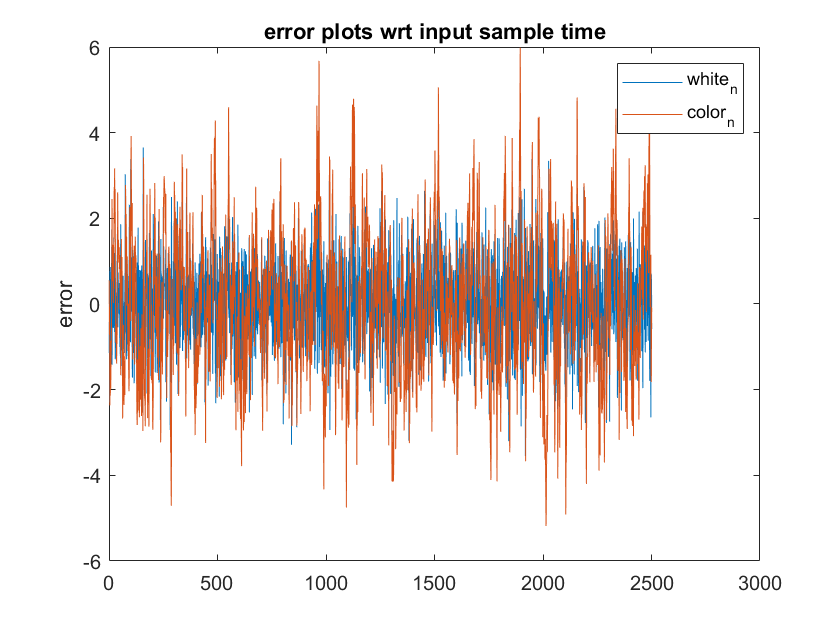

plot(erw)
hold on
plot(erc)
hold off
title("error plots wrt input sample time")
ylabel("error")
legend("white_n", "color_n")